% === Código Integrado ===
clear; clc; close all;

% Parámetros físicos del sistema
m1 = 1; m2 = 1; l1 = 0.5; l2 = 0.5;
k1 = 100; k2 = 100; g = 9.81;

% Parámetros de diseño del controlador
ts = 0.8;              
zeta = 1;             
wn = 4/(zeta*ts);     

Kp = wn^2;
Kd = 2*zeta*wn;

% Estado inicial
x0 = [0; 0; 0; 0];

%% === PRIMERA SIMULACIÓN: Referencia Constante ===
disp('Simulación 1: Referencia Constante');

Simulación 1: Referencia Constante


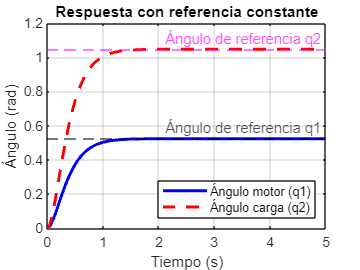


tspan1 = [0 5];  % tiempo para referencia constante
yd_const = [pi/6; pi/3];  % q1=30°, q2=60°

[t1, x1] = ode45(@(t,x) flexible_joint_const(t, x, yd_const, Kp, Kd, m1, m2, l1, l2, k1, k2, g), tspan1, x0);

% Gráfica para referencia constante
figure;
plot(t1, x1(:,1), 'b-', 'LineWidth', 2); hold on;
plot(t1, x1(:,2), 'r--', 'LineWidth', 2);
yline(yd_const(1), '--k', 'Ángulo de referencia q1');
yline(yd_const(2), '--m', 'Ángulo de referencia q2');
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
title('Respuesta con referencia constante');
legend('Ángulo motor (q1)', 'Ángulo carga (q2)', 'Location', 'southeast');
grid on;
hold off;


%% === SEGUNDA SIMULACIÓN: Referencia Escalonada ===
disp('Simulación 2: Referencia Escalonada');

Simulación 2: Referencia Escalonada


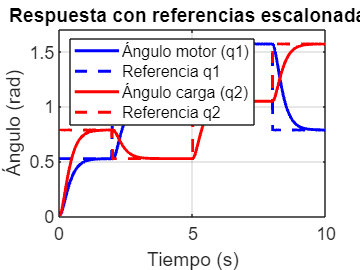


tspan2 = [0 10];  % tiempo para referencia escalonada

[t2, x2] = ode45(@(t,x) flexible_joint_escalonada(t, x, Kp, Kd, m1, m2, l1, l2, k1, k2, g), tspan2, x0);

% Crear manualmente las referencias escalonadas
yd1 = zeros(size(t2));
yd2 = zeros(size(t2));
for i = 1:length(t2)
    if t2(i) < 2
        yd1(i) = pi/6;
        yd2(i) = pi/4;
    elseif t2(i) < 5
        yd1(i) = pi/3;
        yd2(i) = pi/6;
    elseif t2(i) < 8
        yd1(i) = pi/2;
        yd2(i) = pi/3;
    else
        yd1(i) = pi/4;
        yd2(i) = pi/2;
    end
end

% Gráfica para referencia escalonada
figure;
plot(t2, x2(:,1), 'b-', 'LineWidth', 2); hold on;
plot(t2, yd1, 'b--', 'LineWidth', 2);
plot(t2, x2(:,2), 'r-', 'LineWidth', 2);
plot(t2, yd2, 'r--', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
title('Respuesta con referencias escalonadas');
legend({'Ángulo motor (q1)', 'Referencia q1', 'Ángulo carga (q2)', 'Referencia q2'}, 'Location', 'northwest');
grid on;
xlim([0 10]);
ylim([0 1.7]);
set(gca, 'FontSize', 12);
hold off;


%% === Funciones del sistema ===

% Función para referencia constante

function dx = flexible_joint_const(~, x, yd, Kp, Kd, m1, m2, l1, l2, k1, k2, g)
    q1 = x(1); q2 = x(2); q1_dot = x(3); q2_dot = x(4);
    
    M = [m1*l1^2 + m2*l2^2, 0; 0, m2*l2^2];
    C = [0, 0; 0, 0];
    K = [k1, 0; 0, k2];
    G = [m1*g*l1*sin(q1) + m2*g*l2*sin(q1);
         m2*g*l2*sin(q2)];
     
    y = [q1; q2];
    e = y - yd;
    e_dot = [q1_dot; q2_dot];
    
    v = -Kp*e - Kd*e_dot;
    tau = M*v + C*[q1_dot; q2_dot] + K*y + G;
    
    q_ddot = M \ (tau - C*[q1_dot; q2_dot] - K*y - G);
    
    dx = [q1_dot;
          q2_dot;
          q_ddot(1);
          q_ddot(2)];
end

% Función para referencia escalonada
function dx = flexible_joint_escalonada(t, x, Kp, Kd, m1, m2, l1, l2, k1, k2, g)
    q1 = x(1); q2 = x(2); q1_dot = x(3); q2_dot = x(4);

    M = [m1*l1^2 + m2*l2^2, 0; 0, m2*l2^2];
    C = [0, 0; 0, 0];
    K = [k1, 0; 0, k2];
    G = [m1*g*l1*sin(q1) + m2*g*l2*sin(q1);
         m2*g*l2*sin(q2)];
     
    yd = [reference(t, 1); reference(t, 2)];
    
    y = [q1; q2];
    e = y - yd;
    e_dot = [q1_dot; q2_dot];
    
    v = -Kp*e - Kd*e_dot;
    tau = M*v + C*[q1_dot; q2_dot] + K*y + G;
    
    q_ddot = M \ (tau - C*[q1_dot; q2_dot] - K*y - G);
    
    dx = [q1_dot;
          q2_dot;
          q_ddot(1);
          q_ddot(2)];
end

% Función de referencias escalonadas
function yd = reference(t, joint)
    if t < 2
        if joint == 1
            yd = pi/6;
        else
            yd = pi/4;
        end
    elseif t < 5
        if joint == 1
            yd = pi/3;
        else
            yd = pi/6;
        end
    elseif t < 8
        if joint == 1
            yd = pi/2;
        else
            yd = pi/3;
        end
    else
        if joint == 1
            yd = pi/4;
        else
            yd = pi/2;
        end
    end
end
